#         Getting Started with LazyPlot

## Description

LazyPlot can be used to both quickly display a figure containing any number of lines and data sets each.

It will also define the axes ranges of the figure, as well as title, x/ylabel, the position labels of the legend. In addition, by defining the vector "LPQS" before calling "LazyPlot", one can get a quicker glance at the figure by sacrificing some features. Clear out the variable again to enter normal mode again. 

For more information on how to use LazyPlot, open the "LPCodeComp.m"-file. The changelog can have some information about how this came to be. I'd advise reading through the v.1.5 notes, it contains a few useful information on how to operate LazyPlot.

LazyPlot can only plot if all matrices are of the same size. Use NaN to fill up missing data spots, or just call it a second time and plot into the same figure. For more information, type "help LazyPlot" into the command window and read the first section.

The multiple commented matrices in the LPCodeComp-script show other methods for calling LazyPlot.

## System Requirements

-

## Suggestion

It is necessary to predefine the matrices LPmatx and LPmaty (in case of errorbars also either or all of the errormatrices LPmaterrorx/LPmaterrory) before calling LazyPlot.

Regarding the LPQS-variable: It enables a shortened mode of LazyPlot which disables certain features/options in order to give you a quick preview of the actual figure you're plotting. Type "help LazyPlot" for more details on what is disabled.

IMPORTANT: the mode stays active as long as LPQS exists. If you wish to return to the normal mode, delete LPQS from your variables.

If you want, you can to take a look at the changelog.txt file and read the changelog on v.1.5.2.0. and v.1.5.0.0/v.1.5.0.1. They contain some more or less useful information not necessarily on what is happening behind the scenes, but why that might be the case. Or you could just look at the code itself.

## Features

LazyPlot is a toolbox for extensive plotting of data in 2D using any standard matlab fit model with minimal coding effort. It will create fits for the data, and plot those, as well as any Errorbar that it has data for. Reminder: The Errorbar-vectors LPmaterrorx/LPmaterrory can contain NaN values, but if they exist, they need to be of same size as the LPmatx/LPmaty vectors.

## Overview

How to use LazyPlot:

LazyPlot requires 2-4 matrices and one optional variable to be defined before calling LazyPlot.

### Vital (Required) matrices

The matrices LPmatx and LPmaty must be defined in order for LazyPlot to work. The matrices must be structured in a certain way:

Each row of both matrices (and of the optional errormatrices LPmaterrorx and LPmaterrory) are used as data for one graph to be plotted. The dimensions of LPmatx and LPmaty (and their respective error-matrices) must agree. Individualised errors are thrown if this is not the case. 

The dimensions that all matrices are checked against are those of LPmaty. LPmaty must be defined completely.

Exception: If LPmatx has less rows than LPmaty, the first row of LPmatx is duplicated until the dimensions of LPmatx and LPmaty agree. This only happens for LPmatx, as it can be assumed that the x-matrix is often containing the same row vector for different y-vectors.

### Optional Inputs

The matrices LPmaterrorx and LPmaterrory are optional in that they are not necessary for LazyPlot to work. If errorbars are to be plotted, the respective matrix must exist. Errorbars are plotted symmetrically, according to:

errorbar(x,y,errory,errory,errorx,errorx)

Unrecognized function or variable 'x'.

Look into the documentation on [errorbars](https://www.mathworks.com/help/matlab/ref/errorbar.html) for more information.

If one only wants to display errorbars in certain direction, or on certain points, replace the positions in the matrix you don't want errorbars on with NaN-fillers.

Non-defined Errormatrices are autopopulated with NaN-values to allow the code to run successfully, but they won't be plotted visually.

However, if you open a datatip on a point with NaN-errors, they are still displayed on that datatip.

The last, optional Input, is a vector called "LPQS".

More information on that will be given in the respective section.

## Procedures

Yes, plural.

LazyPlot can be run in either one of two modes:

"Normal Mode" and "QuickSketch mode"

### Prerequisites

LazyPlot will check the following criteria before allowing the script to go on:

- Existance of the vital matrices LPmatx and LPmaty

- Existance of the optional matrices LPmaterrorx and LPmaterrory

- Existance of the optional vector LPQS

- Equal size of matrices LPmatx and LPmaty*

- If exist: equal size of LPmaterrorx and LPmaterrory*

- Class of LPmatx, LPmaty, LPmaterrorx and LPmaterrory** 

 *  Size checks are done with LPmaty as the template. all dimensions are checked with the assumption that the dimensions of LPmaty           are correct.

** All matrices must be of class double.

If the errormatrices LPmaterrorx and LPmaterrory do not exist, they are created containing only NaN-values. This is necessary in order for functions to still work later on in that case.

Individual Errors are thrown if any criteria is not fulfilled.

For further information on those, see Vital inputs and Optional Inputs

The fittypeindx-table is loaded from the file, it is needed later on.

The x- and y-limits for the autoscaling of the plotted graphs later on are defined and stored until needed.

### Normal Mode

Normal Mode allows full customisation of the final figure and allows access to everything LazyPlot has to offer.

#### Figure state

If a figure is already open, you are asked if you want to either

- close the figure, and plot into a newly created one

- keep the figure, but plot into a new one

- keep the figure and plot into it*

 * Existing axis-ranges will be overwritten by the auto-scaling when plotting into an already existing figure. If this is not desired, use the redefine the axis-limits once the corresponding input window opens.

#### Colors [LPColorfun2]

Next, you are asked if you want custom colors. Datapoints and Errorbars are plotted in the same color for each data set. You have 2 options:

-  You choose Custom colors when asked so. You will then be asked to input the colors you want one at a time. This is not recommended for larger amount of data sets (more rows), as the process takes time.

-  You choose no custom colours. In this case, LazyPlot will cycle through the 14 standard colours available to matlab till there are enough triplets to cover all plotted object. The colormatrix used later on is grown from the initial 14 rows by doubling every iteration:

    while LPData.NumColorRows<LPData.NumRows % colors-matrix is duplicated till it is bigger than the number of rows. Overshoots the size in general, but needs fewer loops the more objects are plotted.
            LPData.colors=[LPData.colors;LPData.colors];
            [LPData.NumColorRows,~]=size(LPData.colors);
    end

            This means that the growing of the color-matrix doesn't take as many repetitions of the loop till it is complete.Since resizing a 

            matrix is not recommended because it is slow and requires ressources (especially RAM), growing it in as few cycles at possible 

            is better than keeping the matrix itself at the perfect size. For more information on why this is better, visit the help on    

            [Preallocation](https://www.mathworks.com/help/matlab/matlab_prog/preallocating-arrays.html). 

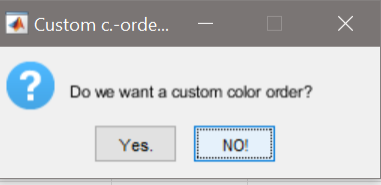

#### Markers [LPCustommarkertypefun2]

After colors, you are asked to define the markers used. This time, you have 3 choices:

- Unified: Choose one of the 13 options, and have all data points use this markertype

- Line-exclusive: Choose one of the 13 options, but unique to each line/set of data points. Not recommended when plotting larger number of data setts, as it takes time because the list-dialogue is opened for every graph again.

- Normal/No: This just cycles through all markertypes until all graphs are plotted. Since we have 14 unique colours, 14 graphs can be plotted with the same marker before the next one is chosen, and still ensure that all graph/marker sets are uniquely identifiable. This rolls over and starts again at the beginning after 182 datasets, but that is probably already far too mucb for one figure to  still be visible.

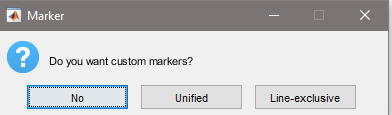

#### Selecting Plottype [LPplottypefun2]

You can choose between different methods of plotting your data. For fitting a fit-line to your data points, choose "line plot". "Data vs Data" also works and was tested.  All other modes have not been properly tested or haven't been worked on properly yet. This might be updated if I get the time, energy (and motivation) to do so. Polar plots are not implemented at all.

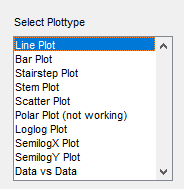

The plottypes are numbered from 1 (Line Plot) to 10 (Data vs Data). The Polar Plot is not working, others are somewhat tested. Line Plots and Data vs Data plots are tested completely and work perfectly.

For fitting a line to your data sets, choose "line plot".

All other modes have not been properly tested or haven't been worked properly yet. This might be updated if I get the time and energy to do so.

#### Selecting Fittype [LPTreePrompter]

If the line plot was chosen, a figure is created showing the data points and straight lines connecting them. This is obviously not fitted, but can help estimating what kind of fit would suit best.

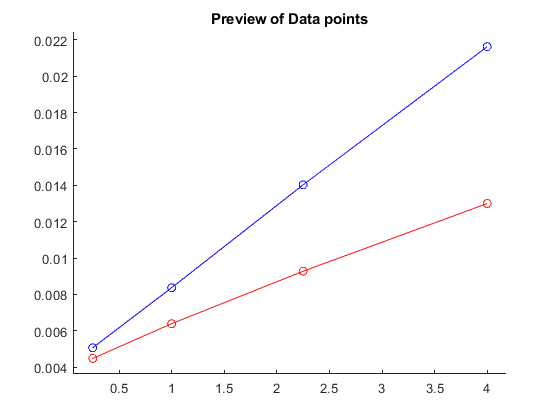

While this figure is visible, a listdlg will open showing all standard fittypes:

 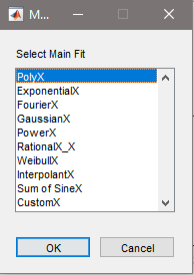     

The "X" at the end f a main fittype shows that there are multiple options available for it. Technically not true for the weibull fit, but in order to make it retracable, the Weibull-fit is moved into a subsection.

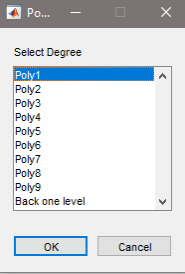

After choosing a general fittype, it can be specified more.

Using the option "Back one level", one can return to the previous screen if one chose the wrong main fit.

        Custom Fits

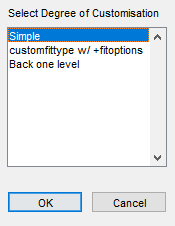

Custom fits can be created as well.

1st Method: Simple

Inputting any valid equation into this field will result in that string being used as a fit type. The corresponding coded version of this, f.e. would be:

    f1=fit(x',y','a*x-b')

The function LPFitfun2 will use the inputs and create the fitobjects. In addition, the goodness-of-fit-parameter and additional information regarding the fit is stored. For more information on how to properly  evaluate the different goodness-of-fit-parameters, visit the Matlab help on [Evaluating Goodness of Fit](https://www.mathworks.com/help/curvefit/evaluating-goodness-of-fit.html).

#### Plotting Graphs [LPPlotfun2]

If one chose "line plot" and a fit type afterwards, the corresponding fits are plotted in the preset interval

    axis([LPData.xlimits(1,1)*1000 LPData.xlimits(1,2)*1000 LPData.ylimits(1,1)*1000 LPData.ylimits(1,2)*1000])

After the graphs are plotted, LazyPlot autoscales the visible part back to the limits defined a the beginning. 

    axis([LPData.xlimits(1,1) LPData.xlimits(1,2) LPData.ylimits(1,1) LPData.ylimits(1,2)])

This ensures that 

a) The graph is plotted over an area which contains all data points.

b) one can see where the fit would go for points outside the data set plotted.

#### Plotting (graphs) [LPPlotfun2]

LPPlotfun2 will plot the plot chosen by LPplottypefun2. For different plottypes several sub-options may be chosen. Since LazyPlot was mainly mean to be used for plotting line plots, its other modes are not polished as much as Line Plots are. I would recommend either writing normal code when doing more specifc/customised versions of other plots instead of using LazyPlot for that. You can obviously alter the original code to implement such possibilities if you want. It wasn't a focus for me, and until it is, this might no

    1. Line Plot

The main plottype LazyPlot is optimized for. Other  plottypes may not be as useful when made using this toolbox, as it is not its main focus. 

In this case, LazyPlot will plot the fits previously created fits. The data points themselves are plotted by the LPErrorbarfun2.

    2 All other plots:

- [Bar Plots](https://www.mathworks.com/help/matlab/ref/bar.html) (note: the histogram plot utilizes the[ histogram2](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram2.html)-command, instead of the hist or histc command which are both found under the bar graph documentation. 

- [Stairstep Plot](https://www.mathworks.com/help/matlab/ref/stairs.html)

- [Stem Plot](https://www.mathworks.com/help/matlab/ref/stem.html)

- [Scatter Plot](https://www.mathworks.com/help/matlab/ref/scatter.html)

- [Loglog Plot](https://www.mathworks.com/help/matlab/ref/loglog.html)

- [Semilogx Plot](https://www.mathworks.com/help/matlab/ref/semilogx.html)

- [Semilogy Plot](https://www.mathworks.com/help/matlab/ref/semilogy.html)

- [Data vs Data plot](https://www.mathworks.com/help/matlab/ref/plot.html#btzptin) ( no fits, just straight line from data point to data point. See matlab documentation for more information)

#### Plotting Errorbars and Datapoints [LPErrorbarfun2]

After the graph itself is plotted, the data points are plotted. This is accomplished in two ways:

    1. Case: Line Plot

The function LPErrorbarfun will plot both the data points with the markers and colors selected by LPCustommarkertypefun2 and LPColorfun2 respectively. if no errormatrices are defined, they are filled with NaN-values, which are not plotted.

%     errorbar(LPData.matx(k,:),LPData.maty(k,:),LPData.materrory(k,:),LPData.materrory(k,:),LPData.materrorx(k,:),LPData.materrorx(k,:),LPData.markertype(k),'Color',LPData.colors(rem(k-1,LPData.NumRows)+1,:)

or, more generally,

%     errorbar(x,y,errory,errory,errorx,errorx,markers,'color',colormatrix)

    2. Case: All other plots

In case of all other plots, if there should be data points, they will be plotted within the LPPlotfun2-function.

####  Figure Properties [LPFigurefun2/LPFigurefun]

LazyPlot itself only utilises LPFigurefun2. It can be used to set customisable axis ranges inside the range predefined.     

Figure Reset

If a figure already exists, you will be asked if you want to close the figure, create a new one, or keep the current. If you keep the current one, new plots will be plotted into it. If you close it, a new figure is created. If you choose a new figure, that's obvious. New figure.

Colors

Plot type

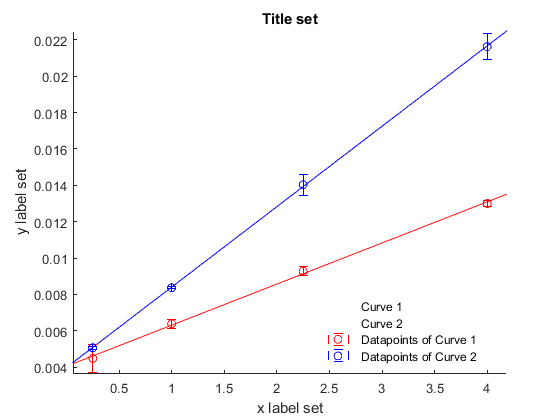

## Examples

%% Example 1: Normal Call
clear variables
% It is HIGHLY recommended to predefine the matrices LPmatx and LPmaty (in
% case of errorbars also either or all of them) before calling LazyPlot.
% Regarding the LPQS-variable: It enables a shortened mode of LazyPlot
% which disables certain features/options in order to give you a quick
% preview of the actual figure you're plotting. Type "help LazyPlot" for
% more details on what is disabled.
% IMPORTANT: the mode stays active as long as LPQS exists. If you wish to
% return to the normal mode, delete LPQS from your variables.
% It is also recommended to take a look at the changelog.txt file, which
% will give you an overview over 

wd=[0.25 1.00 2.25 4.00];
uwd=[0.001 0.001 0.001 0.001];  
J_1=[0.004482938641	0.006391417971 0.009277047706 0.01299910418];
uJ_1=[0.0007472972927 0.0002425672566 0.000244447623 0.0001757093571];
J_2=[0.005069407322 0.008369961302 0.01402633152 0.0216247172];
uJ_2=[0.00009375195973 0.00004638236948 0.0005688667782	0.0007134557535];
LPmatx=wd; 

%%
% Exclusive to the LPmatx-matrix: You can define only one vector of the
% matrix, given that it would be the same for all. LazyPlot will
% then autopopulate the remaining rows of LPmatx with copies to fill up to
% the size of LPmaty.
% You can also define different x-vectors for one plot, given all matrix
% dimensions line up.

LPmaty=[J_1;J_2];
LPmaterrorx=[uwd;uwd];
%LPmaterrorx=[NaN NaN NaN NaN;NaN NaN NaN NaN];
%LPmaterrorx=[uwd;NaN NaN NaN NaN];
%LPmaterrorx=[0.0007472972927 NaN 0.000244447623 0.0001757093571;uwd]; % If you zoom in on the second data point of the red line, you'll see that it only has one errorbar, due to the NaN.
LPmaterrory=[uJ_1;uJ_2];
LazyPlot
clc


%% Example 2: Using NaN to block out certain data if it is missing (Only for Errorbars)
% clear variables
 
wd=[0.25 1.00 2.25 4.00];
uwd=[0.001 0.001 0.001 0.001];
J_1=[0.004482938641	0.006391417971 0.009277047706 0.01299910418];
uJ_1=[0.0007472972927 0.0002425672566 0.000244447623 0.0001757093571];
J_2=[0.005069407322 0.008369961302 0.01402633152 0.0216247172];
uJ_2=[0.00009375195973 0.00004638236948 0.0005688667782	0.0007134557535];
%LPmatx=[wd;0.25 1.00 2.25 4.00]; This vetor would work with LazyPlot
%LPmatx=[wd;0.25 1.00 2.25 NaN]; %this vetor would not work. NaN values can only
%be used for errorbars (LPmaterrorx,LPmaterrory)
%LPmaterrorx=[uwd;uwd];
%LPmaterrorx=[NaN NaN NaN NaN;NaN NaN NaN NaN]; % This on the other hand does work
%LPmaterrorx=[uwd;NaN NaN NaN NaN];
LPmaterrorx=[0.0007472972927 NaN 0.000244447623 0.0001757093571;uwd]; % If you zoom in on the second data point of the red line, you'll see that it only has one errorbar, due to the NaN.
LPmaty=[J_1;J_2];
LPmaterrory=[uJ_1;uJ_2];
clc
LPQS=1
LazyPlot
%If you want to block out values in the LPmatx/LPmaty-vectors, you'll
%need to call LazyPlot multiple times and plot all graphs into the same
figure



% Part of the LazyPlot-Toolbox by Claudius Appel.
% For more information, open the main script LazyPlot.